# Miniprojekt 3 - Tone Control

## Indledning

VIl vil i denne opgave vil vi anvende digital signalbehandling til at justere lyden i en Lyngdorf TDAI-1120 forstærker. Vi vil arbejde audiofiltre og lgoritmer til at opnå en løsning. Forstærkeren indeholder en DSP med forskellige features som tonecontrol, Room Correction og Speaker EQ. Vi vil i denne opgave arbejde med Tone Control. 

## Formål

Vi vil analysere og designe tonekontrol som skal kunne ændre på gain af hhv. bassen og diskanten. Tonekontrol er det førsteled i DSP'en som ses i billedet nedenfor.

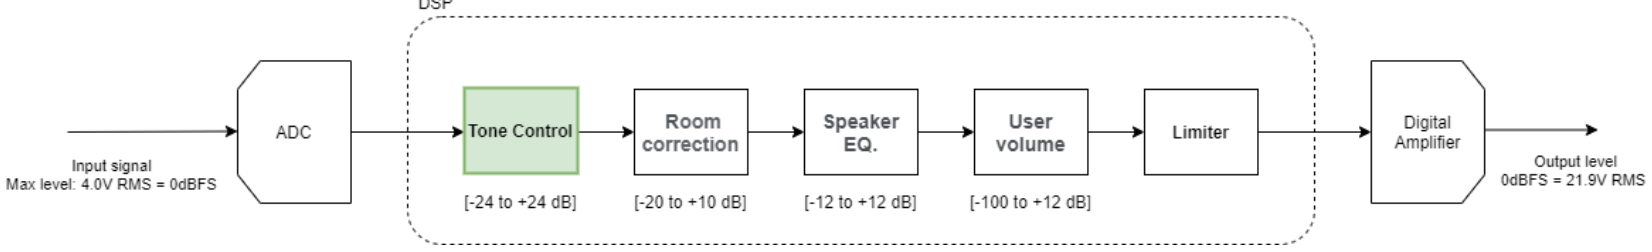

Dette vil vi gøre ved at konstruere to shelving-filtre i kaskade hvor den ene er til bas og den anden til diskant. Kravene er således:

- 2 x IIR filtre (shelving)

- Niveau i hvert bånd +-24dB

## Analyse

Først tages udgangspunkt i diskanten. Ved diskanten skal de høje frekvenser igennem, dvs. et højpas filter skal konstrueres.

Fs = 44.1e3;

gain = 24;

slope1 = 0.5;
slope2 = 0.75;
slope3 = 1;

Fc = 150/(Fs/2);
K=tan(pi*Fc/Fs);
V0=10^(gain/20);

b0=(1+sqrt(2*V0)*K+K^2)/(1+sqrt(2)*K+K^2);
b1=(2*(V0*K^2-1))/(1+sqrt(2)*K+K^2);

b1 = -2.0000

b2=(1-sqrt(2*V0)*K+K^2)/(1+sqrt(2)*K+K^2);
a1=(2*(K^2-1))/(1+sqrt(2)*K+K^2);
a2=((1-sqrt(2)*K+K^2))/(1+sqrt(2)*K+K^2);


B1 = [b0, b1, b2]

B1 =     1.0000   -2.0000    1.0000


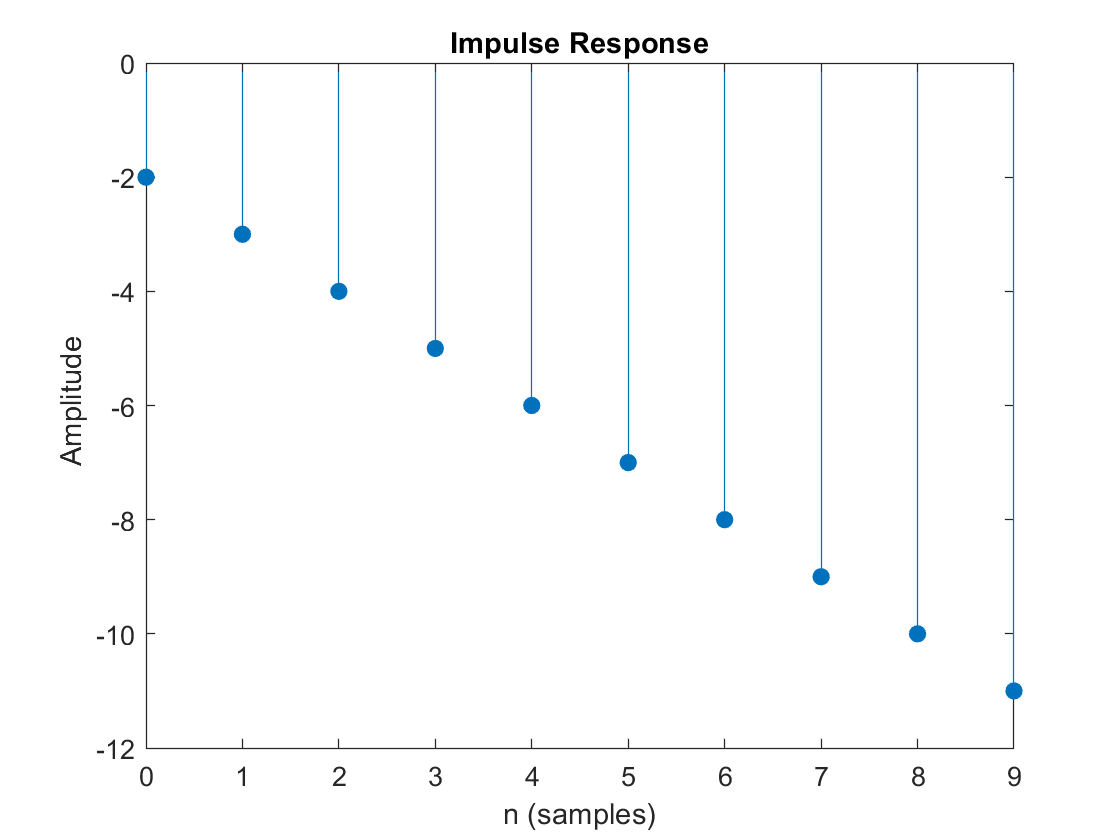

A1 = [a1, a2];

impz(A1,B1)

H =   -0.0000 + 0.0000i  -0.4000 - 0.8000i  -1.3333 + 0.0000i  -0.4000 + 0.8000i


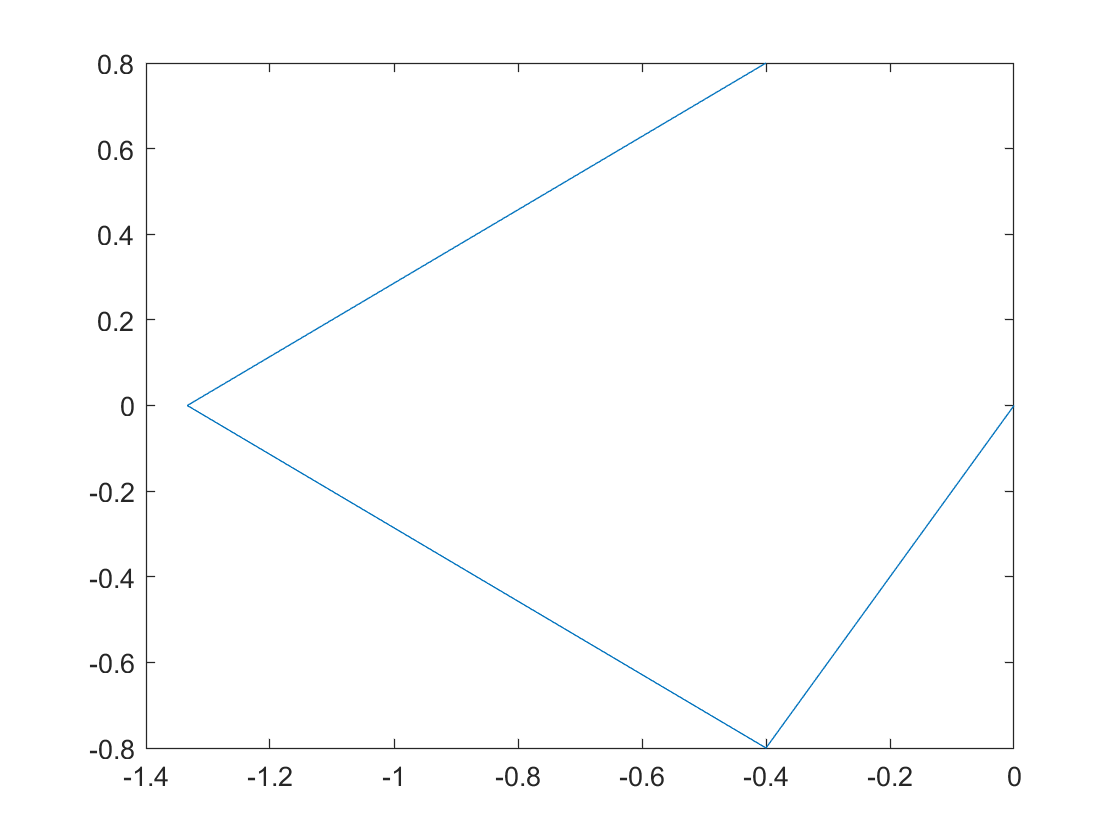

H=fft(B1,4)./fft(A1,4)

%[B1,A1] = designShelvingEQ(gain,slope1,Fc,"Orientation","row")

Unrecognized function or variable 'DFTFilter'.